filepathin='D:\matlab\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png'

filepathin = 'D:\matlab\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png'

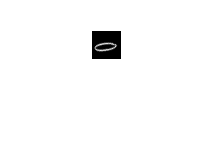

Imagein = imread(filepathin);
imshow(Imagein)

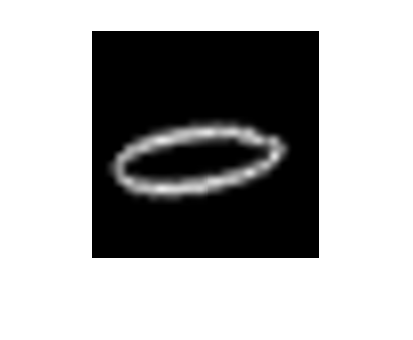

if numel(size(Imagein)) == 2
    Imageout1 = cat(3,Imagein,Imagein,Imagein);% 用于将图片改为3通道
end
Imageout = imresize(Imageout1,[227,227]);
imshow(Imageout)

S = regexp(filepathin, '\', 'split');
filepathouthead='C:\Users\coding\Desktop\matlab作业\结课作业\图片集\';
filepathout=strcat(filepathouthead,S(end-1),'\',S(end));
filepathout=filepathout{1,1};
imwrite(Imageout,filepathout);